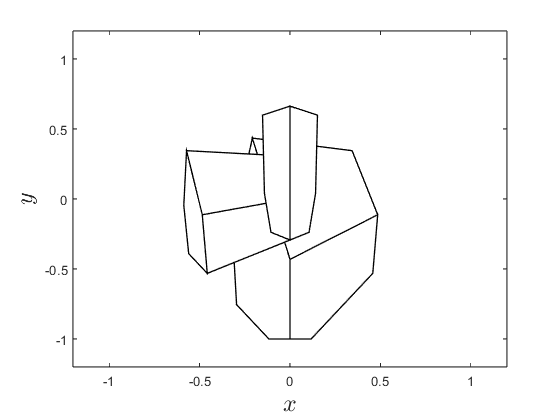

clear

% Load clipped space coordinates
load('clipped_space_co-ordinates.mat')

% Determine front facing polygons
Ffront = backface_culling(Vclipped, Fclipped, [0;0;1]);

% Save front facing polygons
save('front_facing_coordinates', 'Vclipped', 'Ffront')

% Plot front facing polygons space (from viewing position)
figure
hold on
for i = 1 : size(Ffront, 1)
    x = zeros(1, size(Ffront,2));
    y = zeros(1, size(Ffront,2));
    for j = 1 : size(Ffront, 2)
        x(j) = Vclipped(1,Ffront(i,j));
        y(j) = Vclipped(2,Ffront(i,j));
    end
    fill(x, y, 'w', LineWidth=1)
end

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
box on
exportgraphics(gcf,'../images/backface_culling_example.png','Resolution',300) 

function Ffront = backface_culling(V, F, p)

Ffront = [];
for i = 1 : size(F, 1)
    v1 = V(1:3, F(i,1));
    v2 = V(1:3, F(i,2));
    v3 = V(1:3, F(i,3));
    n = cross(v2 - v1, v3 - v2);
    if dot(n, v1 - p) < 0
        Ffront = [Ffront ; F(i,:)];
    end
end

end


function [Vclipped, Fclipped] = clipped_space(V, F)

% Define visible region points and normal vectors
P = [ -1, -1,  1,  1, -1, 1 ; 
      -1, -1,  1,  1, -1, 1 ; 
       1,  1, -1, -1,  1, -1 ];
n = [ 0,  0, -1, 0, 1,  0 ;  
      1,  0,  0, 0, 0, -1 ; 
      0, -1,  0, 1, 0,  0 ];

% Loop through the polygons in F
Vclipped = V;
Fclipped = [];
for poly = 1 : size(F, 1)

    % Loop through the edges of the clipping cube
    outputlist = F(poly, :);
    for edge = 1 : size(P,2)
        inputlist = outputlist;
        outputlist = [];

        for i = 1 : length(inputlist)
            current = inputlist(i);
            if i > 1
                previous = inputlist(i - 1);
            else
                previous = inputlist(end);
            end

            % Calculate intersection point
            dcurrent = dot(Vclipped(1:3,current) - P(:,edge), n(:,edge));
            dprevious = dot(Vclipped(1:3,previous) - P(:,edge), n(:,edge));
            if dcurrent - dprevious ~= 0
                t = dprevious / (dprevious - dcurrent);
                intersection = [Vclipped(1:3,previous) + t * (Vclipped(1:3,current) - Vclipped(1:3,previous)) ; 1];
            end

            % Check if polygon edge crosses clipping cube edge
            if dcurrent > 0 
                % if previous point is outside add intersection to output list
                if dprevious < 0 
                    Vclipped = [Vclipped, intersection];
                    outputlist = [outputlist, size(Vclipped, 2)];
                end
                outputlist = [outputlist, current];

            elseif dprevious > 0
                % current point is outside and previous point is inside so add
                % intersection to output list
                Vclipped = [Vclipped, intersection];
                outputlist = [outputlist, size(Vclipped, 2)];
            end
        end
    end

    % If outputlist is non-empty add to Fclipped
    if isempty(outputlist) == 0
        nclippedverts = length(outputlist);

        if isempty(Fclipped)
            Fclipped = outputlist;
            maxverts = length(outputlist);
        else
            if maxverts < nclippedverts
                % Pad out Fclipped if number of clipped vertices is greater
                % than current maxverts
                Fclipped = [Fclipped, zeros(size(Fclipped, 1), nclippedverts - maxverts)];
                Fclipped(:,maxverts + 1 : end) = Fclipped(:, maxverts);
                maxverts = nclippedverts;

            elseif maxverts > length(outputlist)
                % Pad out outputlist if number of clipped vertices is less than
                % current maxverts
                outputlist = [outputlist, ones(1,maxverts - nclippedverts) * outputlist(end)];
            end

            % Add outputlist to Fclipped
            Fclipped = [Fclipped ; outputlist];
        end
    end

end

end
